clear all
close all

addpath('../dasf_toolbox/');

Solve the the following Quadratically Constrained Quadratic Problem (QCQP):


$$\text{arg}\min_X \frac{1}{2} \mathbb{E}[||X^T\mathbf{y}(t)||^2]-\text{tr}\left(X^TB\right)\\
\text{s.t. } \text{tr}\left(X^TX)\leq \alpha^2,\; X^T\mathbf{c}=\mathbf{d},$$


in a distributed context using the Distributed Adaptive Signal Fusion (DASF) framework.

Let us first define the network. We take a randomly connected network with 10 nodes and 5 channels per node.

nbnodes=10;
nbsensors_vec=5*ones(nbnodes,1);
nbsensors=sum(nbsensors_vec);
adj=randi(2,nbnodes,nbnodes)-1;
graph_adj=triu(adj,1)+tril(adj',-1);
non_connected=find(all(graph_adj==0));
% If there are non-connected nodes, connect them to every other node.
if(non_connected)
    graph_adj(:,non_connected)=1;
    graph_adj(non_connected,:)=1;
end

Next, we create the data using 

found at the end of this file. The number of time samples of the signals is 10000 and we choose the number of filters to be equal to 3, i.e., $X$ has 3 columns.

nbsamples=10000;
Q=3;
[Y,B,alpha,c,d]=create_data(nbsensors,nbsensors_vec,nbnodes,nbsamples,Q);

The data are stored in 4 different cells, 

- One for the (stochastic) signals. In this example, the cell contains only one element, the signal $\mathbf{y}$. 

Y_cell{1}=Y;

- One for deterministic constant matrices. In this example, we have two of them $B$ and $\mathbf{c}$.

B_cell{1}=B;
B_cell{2}=c;

- One for quadratic terms. Here, we have only one, which is the identity matrix.

Gamma_cell{1}=eye(nbsensors);

- The final one for global constraint parameters, i.e., those that are not filtered using $X$. In this case, we have $\alpha$ and $\mathbf{d}$.

Glob_Const_cell{1}=alpha;
Glob_Const_cell{2}=d;

We then create structures for the data, problem parameters and stopping criteria called 

respectively:

data=struct;
data.Y_cell=Y_cell;
data.B_cell=B_cell;
data.Gamma_cell=Gamma_cell;
data.Glob_Const_cell=Glob_Const_cell;

prob_params=struct;
prob_params.nbsensors=nbsensors;
prob_params.Q=Q;
prob_params.nbnodes=nbnodes;
prob_params.nbsensors_vec=nbsensors_vec;
prob_params.nbsamples=nbsamples;
prob_params.graph_adj=graph_adj;

We fix the number of iterations the DASF algorithm will perform to 200.

conv=struct;
conv.nbiter=200;

We choose a randomly selected updating order for the distributed implementation:

prob_params.update_path=randperm(nbnodes);
prob_params.update_path

ans =      6     8     3     5     4     9     2     7     1    10


Then, an optimal filter $X^*$ solving the QCQP is estimated using the centralized algorithm: 

[X_star,f_star]=qcqp_solver(prob_params,data);
prob_params.X_star=X_star;
% Compute the distance to X^* if "true".
prob_params.compare_opt=true;
% Show a dynamic plot if "true".
prob_params.plot_dynamic=false;

The distributed implementation is then called using the function 

 which takes as parameters the data, problem parameter and stopping criteria structures along with the functions 

which evaluates the QCQP objective given a certain $X$ and solves the centralized QCQP, respectively. In this example, we do not require a function which resolves the uniqueness ambiguity of the problem since there is a unique $X$ solving the problem, which is why we leave its argument slot empty.

[X_est,norm_diff,norm_err,f_seq]=dasf(prob_params,data,...
                    @qcqp_solver,conv,[],@qcqp_eval);

Let us plot the normalized error $\epsilon$ given by:

$\epsilon(X^i)=\frac{||X^i-X^*||_F^2}{||X^*||_F^2}$,

which is stored in

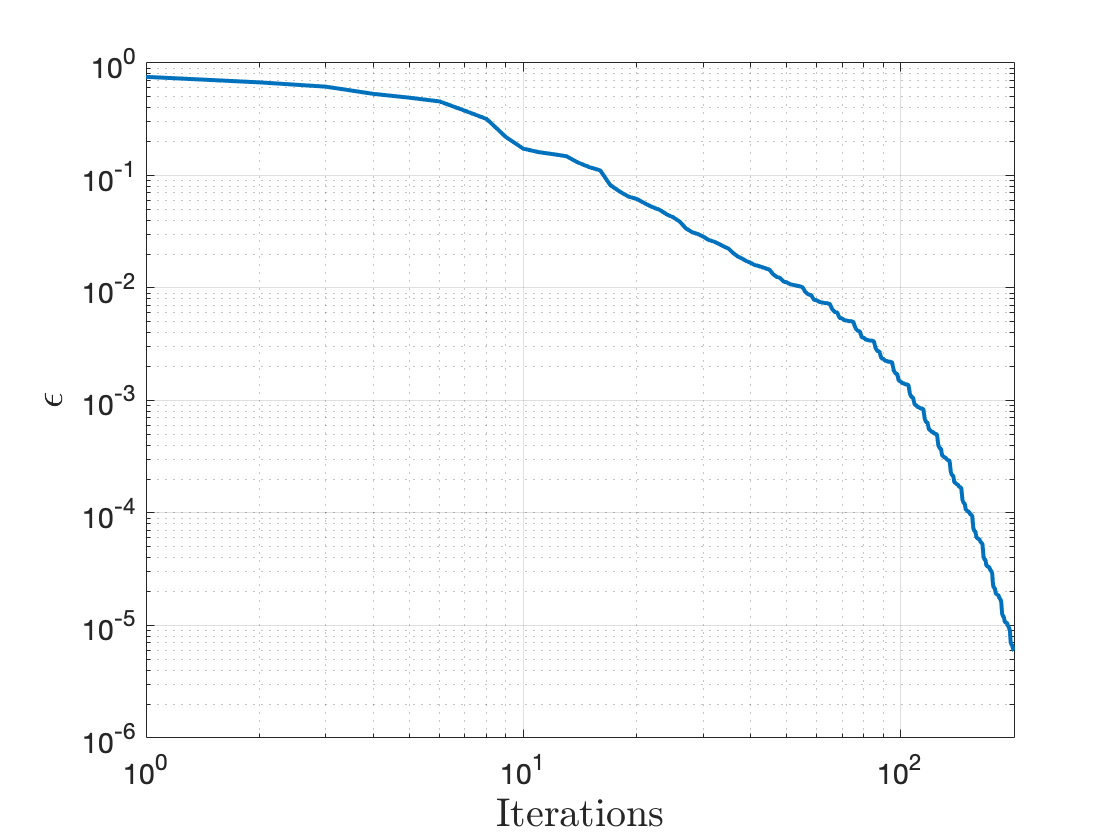

loglog([1:200],norm_err,'LineWidth',2)
ax=gca;
ax.FontSize=14;
xlabel('Iterations','Interpreter','latex','Fontsize',20)
ylabel('$\epsilon$','Interpreter','latex','Fontsize',20)
xlim([1,inf])
grid on

Functions used to create the data of the problem.

function [Y,B,alpha,c,d]=create_data(nbsensors,nbsensors_vec,nbnodes,nbsamples,Q)

    rng('shuffle');
    % Create signal.
    Y=create_signal(nbsamples,nbsensors_vec,nbnodes);
    Ryy=1/nbsamples*conj(Y*Y');
    Ryy=make_sym(Ryy);
    % Generate other paramaeters.
    B=randn(nbsensors,Q);
    c=randn(nbsensors,1);
    d=randn(Q,1);
    w=(B'*inv(Ryy)'*c-d)./(c'*inv(Ryy)*c);
    X=inv(Ryy)*(B-c*w');
    
    toss=randi(2)-1;
    
    if toss==0
        alpha=randn(1,1);
        alpha=alpha^2;
        
    % Enforce the solution to be strictly satisfying the inequality
    % constraint.
    else
        alpha=randn(1,1);
        alpha=alpha^2;
        alpha=sqrt(norm(X,'fro')^2+alpha^2);
    end

    % If problem is infeasible, recreate the parameters.
    while(alpha^2<norm(d)^2/norm(c)^2)
        c=randn(nbsensors,1);
        d=randn(1,1);
        w=(B'*inv(Ryy)'*c-d)/(c'*inv(Ryy)*c);
        X=inv(Ryy)*(B-c*w');
        toss=randi(2)-1;
        if toss==0
            alpha=randn(1,1);
            alpha=alpha^2;
        else
            alpha=randn(1,1);
            alpha=alpha^2;
            alpha=sqrt(norm(X,'fro')^2+alpha^2);
        end
    end

end

function Y=create_signal(nbsamples,nbsensors_vec,nbnodes)

    signalvar=0.5;
    noisepower=0.1;
    nbsources=10;
    offset=0.5;
    
    rng('shuffle');
    S=randn(nbsources,nbsamples);
    S=sqrt(signalvar)./(sqrt(var(S,0,2))).*(S-mean(S,2)*ones(1,nbsamples));

    for k=1:nbnodes
        A{k}=rand(nbsensors_vec(k),nbsources)-offset;
        noise{k}=randn(nbsensors_vec(k),nbsamples); 
        noise{k}=sqrt(noisepower)./sqrt(var(noise{k},0,2)).*(noise{k}...
            -mean(noise{k},2)*ones(1,nbsamples));
    end

    column_blk=0;

    for k=1:nbnodes
        Y_cell{k}=A{k}*S+noise{k};
        Y(column_blk+1:column_blk+nbsensors_vec(k),1:nbsamples)=Y_cell{k};
        column_blk=column_blk+nbsensors_vec(k);
    end

end